clear
clc
close all
loadnetfk = true; %load net fk
addpath("robt403lab7_IK_ML_Yerzhan_not_tuned/");
addpath("..");

planarrobot_student

ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


 
planar_robot = 
 
planar_robot:: 5 axis, RRRRR, stdDH, slowRNE                     
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|       0.59|          0|          0|
|  2|         q2|          0|       0.59|          0|          0|
|  3|         q3|          0|       0.59|          0|          0|
|  4|         q4|          0|       0.59|          0|          0|
|  5|         q5|          0|       0.59|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


home = [45 45 0 45 -45]*deg;
planar_robot.plot(home)
pose_end = planar_robot.fkine(home);
hold on
%real
xyz = transl(pose_end)

xyz =     0.0000    2.6044         0


scatter3(xyz(1),xyz(2),xyz(3),100)

% predicted
if loadnetfk
    load net_fk.mat    
else
    load 'Trained values 500.mat'
end

sample = ones(1,1,5);
sample(1,1,:) = home;

xyz = transl(pose_end)

xyz =     2.0605    0.9202         0


xyz2 = predict(net_fk, sample)

xyz2 = 1×3 single row vector
   -0.0023    2.6252   -0.0008


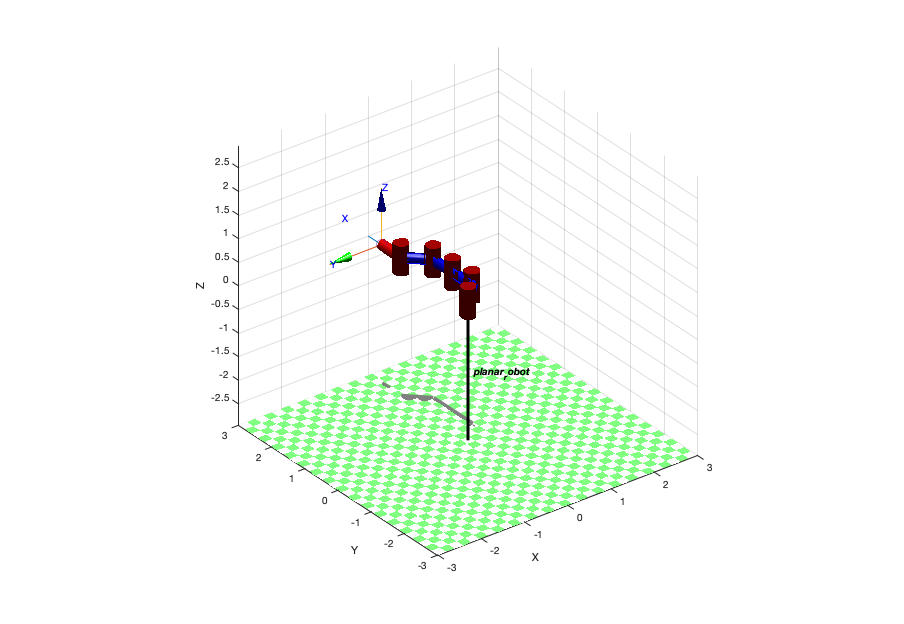

hold on
scatter3(xyz2(1),xyz2(2),xyz2(3),'*')


error = mean(sqrt((xyz(1)-pr_xyz(1))^2 + (xyz(2)-pr_xyz(2))^2 + (xyz(3)-pr_xyz(3))^2))

error = single
0.0105